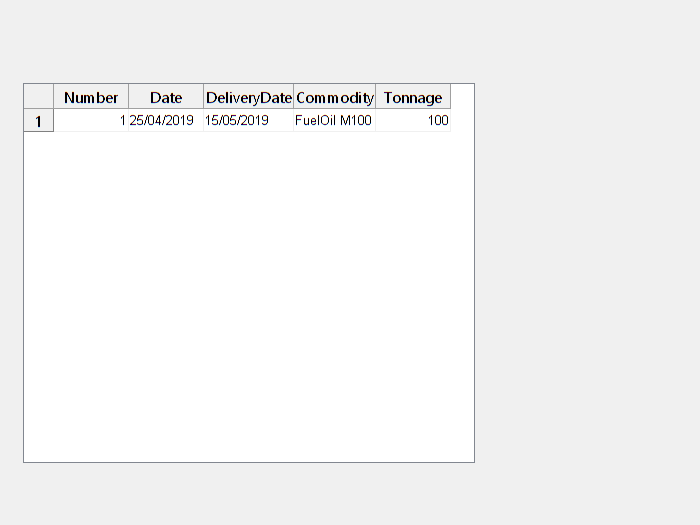

Company = struct('Name',{'Lukoil'},'Director',{'D1'},'Manager',{'M1'},'Secretary',{'S1'},'Lawer',{'L1'},'Accountant',{'A1'});

Buyer = Company;
xls_statutorydocument_generator('StatutoryDocument',Buyer);

Company = struct('Name',{'KrasnodarskyNPZ'},'Director',{'D2'},'Manager',{'M2'},'Secretary',{'S2'},'Lawer',{'L2'},'Accountant',{'A2'});
Seller = Company;
xls_statutorydocument_generator('StatutoryDocument',Seller);

Transaction_Proposed = struct('Number',{1},'Date',{'25/04/2019'},'DeliveryDate',{'15/05/2019'},'Commodity',{'FuelOil M100'},'Tonnage',{100});
%Transaction_Proposed = transaction_request(Transaction_Proposed,Buyer,Seller);
xls_agreement_generator('Agreement',Transaction_Proposed, Buyer,Seller);

TitleCells = fieldnames(Transaction_Proposed); 
DataCells = struct2cell(Transaction_Proposed);

%Gui_dynamic
fgui_dynamic(TitleCells', DataCells');